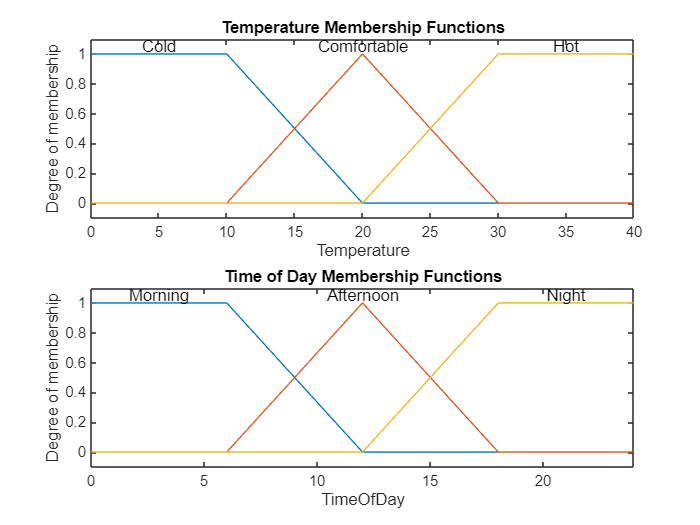

%% Fuzzy Logic Controller for Temperature and Time of Day
% Create Mamdani FIS object
fis = mamfis('Name', 'TemperatureTimeController', ...
    'AndMethod', 'min', ...
    'OrMethod', 'max', ...
    'ImplicationMethod', 'min', ...
    'AggregationMethod', 'max', ...
    'DefuzzificationMethod', 'centroid');

%% Input Variables
% Input 1: Temperature (0°C to 40°C)
fis = addInput(fis, [0 40], 'Name', 'Temperature');
fis = addMF(fis, 'Temperature', 'trapmf', [0 0 10 20], 'Name', 'Cold');
fis = addMF(fis, 'Temperature', 'trimf', [10 20 30], 'Name', 'Comfortable');
fis = addMF(fis, 'Temperature', 'trapmf', [20 30 40 40], 'Name', 'Hot');

% Input 2: Time of Day (0 to 24 hours)
fis = addInput(fis, [0 24], 'Name', 'TimeOfDay');
fis = addMF(fis, 'TimeOfDay', 'trapmf', [0 0 6 12], 'Name', 'Morning');
fis = addMF(fis, 'TimeOfDay', 'trimf', [6 12 18], 'Name', 'Afternoon');
fis = addMF(fis, 'TimeOfDay', 'trapmf', [12 18 24 24], 'Name', 'Night');

%% Output Variable
% Output: Heater Power (0% to 100%)
fis = addOutput(fis, [0 100], 'Name', 'HeaterPower');
fis = addMF(fis, 'HeaterPower', 'trimf', [0 25 50], 'Name', 'Low');
fis = addMF(fis, 'HeaterPower', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'HeaterPower', 'trimf', [50 75 100], 'Name', 'High');

%% Rule Base
rules = [
    "If Temperature is Cold and TimeOfDay is Morning then HeaterPower is High";
    "If Temperature is Cold and TimeOfDay is Afternoon then HeaterPower is Medium";
    "If Temperature is Cold and TimeOfDay is Night then HeaterPower is High";
    "If Temperature is Comfortable and TimeOfDay is Morning then HeaterPower is Medium";
    "If Temperature is Comfortable and TimeOfDay is Afternoon then HeaterPower is Low";
    "If Temperature is Comfortable and TimeOfDay is Night then HeaterPower is Medium";
    "If Temperature is Hot and TimeOfDay is Morning then HeaterPower is Low";
    "If Temperature is Hot and TimeOfDay is Afternoon then HeaterPower is Low";
    "If Temperature is Hot and TimeOfDay is Night then HeaterPower is Medium";
];

fis = addRule(fis, rules);

%% Visualization
% Membership functions for inputs
figure('Name','Membership Functions for Inputs');
subplot(2,1,1); plotmf(fis,'input',1); title('Temperature Membership Functions');
subplot(2,1,2); plotmf(fis,'input',2); title('Time of Day Membership Functions');

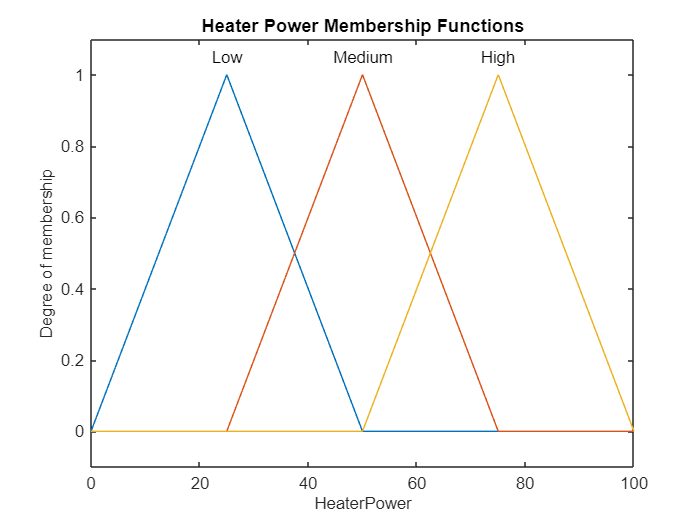


% Membership functions for output
figure('Name','Membership Functions for Output');
plotmf(fis,'output',1); title('Heater Power Membership Functions');

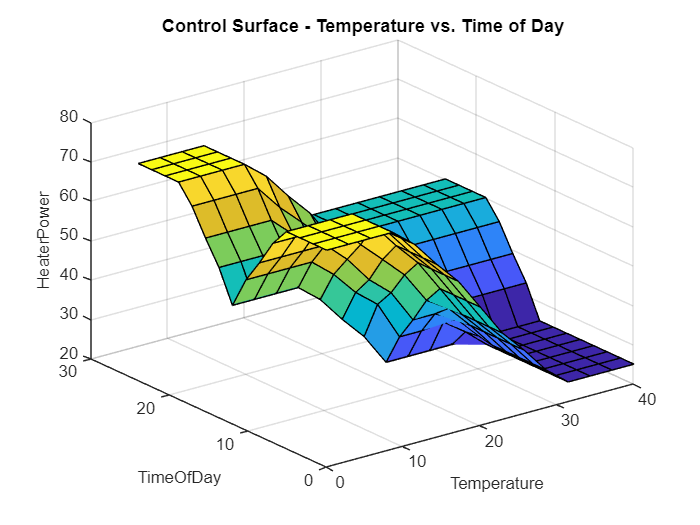


% Control surface plot
figure('Name','Control Surface');
gensurf(fis);
title('Control Surface - Temperature vs. Time of Day');


%% Simulation
% Test sample input (e.g., Temperature = 15°C, Time of Day = 8 hours)
inputValues = [15, 8];
output = evalfis(fis, inputValues);
fprintf('For Temperature=%.2f°C and TimeOfDay=%.2f hours:\nHeater Power: %.2f%%\n\n',...
        inputValues(1), inputValues(2), output);

For Temperature=15.00°C and TimeOfDay=8.00 hours:
Heater Power: 52.85%



% Example inputs
testInputs = [
    [5, 9]; % Cold morning
    [25, 15]; % Comfortable afternoon
    [35, 21]; % Hot night
];

% Evaluate system for each input
for i = 1:size(testInputs,1)
    output = evalfis(fis, testInputs(i,:));
    fprintf('For Temperature=%.2f°C and TimeOfDay=%.2f hours:\nHeater Power: %.2f%%\n\n',...
            testInputs(i,1), testInputs(i,2), output);
end

For Temperature=5.00°C and TimeOfDay=9.00 hours:
Heater Power: 62.50%

For Temperature=25.00°C and TimeOfDay=15.00 hours:
Heater Power: 37.50%

For Temperature=35.00°C and TimeOfDay=21.00 hours:
Heater Power: 50.00%



fuzzyLogicDesigner(fis);